% load the sound recording of the whiskers on galvo for sup. figures
cd /media/ben/'Extreme SSD'/Thesis/Objects_IC/

[aluminum,sf] = audioread('Aluminumlvo0002178.wav');
attenuated = audioread('Attenuatedlvo0002177.wav');
noObject = audioread("Nonlvo0002176.wav");

galvoT_alum = readtable('Aluminumlvo0002178.txt');
galvoT_att = readtable('Attenuatedlvo0002177.txt');
galvoT_non = readtable('Nonlvo0002176.txt');

alumMouse = audioread('mouse1_aluminum_1.wav');
attMouse = audioread('mouse1_attenuated_1.wav');
noMouse = audioread('mouse1_NoObject_1.wav');

load('whisking_periods_aluminum_1.mat');
load("whisking_periods_attenuated_1.mat");
load("whisking_periods_NoObject_1.mat");

cd /home/ben/Music/Cleaned_audio/
load('volt2pascal.mat')

aluminum = aluminum*transferFunction/gainF;
attenuated = attenuated*transferFunction/gainF;
noObject = noObject*transferFunction/gainF;


alumMouse = alumMouse*transferFunction/gainF;
attMouse = attMouse*transferFunction/gainF;
noMouse = noMouse*transferFunction/gainF;


% load an experiment to show compare

timeAlumMouse = round((whisking_periods_aluminum_1(3)*sf) - 0.35*sf);
timeAlumMouse = [timeAlumMouse-0.5*sf:timeAlumMouse+1.5*sf]

timeAlumMouse =     10270266    10270267    10270268    10270269    10270270    10270271    10270272    10270273    10270274    10270275    10270276    10270277    10270278    10270279    10270280    10270281    10270282    10270283    10270284    10270285    10270286    10270287    10270288    10270289    10270290    10270291    10270292    10270293    10270294    10270295    10270296    10270297    10270298    10270299    10270300    10270301    10270302    10270303    10270304    10270305    10270306    10270307    10270308    10270309    10270310    10270311    10270312    10270313    10270314    10270315


timeAlum = round((galvoT_alum.Var1(2)*sf) - sf*1);
timeAlum = [timeAlum-0.5*sf:timeAlum+1.5*sf]

timeAlum =       140645      140646      140647      140648      140649      140650      140651      140652      140653      140654      140655      140656      140657      140658      140659      140660      140661      140662      140663      140664      140665      140666      140667      140668      140669      140670      140671      140672      140673      140674      140675      140676      140677      140678      140679      140680      140681      140682      140683      140684      140685      140686      140687      140688      140689      140690      140691      140692      140693      140694


timeAttMouse = round((whisking_periods_attenuated_1(1)*sf) - 0.38*sf);
timeAttMouse = [timeAttMouse-0.5*sf:timeAttMouse+1.5*sf]

timeAttMouse =     17064216    17064217    17064218    17064219    17064220    17064221    17064222    17064223    17064224    17064225    17064226    17064227    17064228    17064229    17064230    17064231    17064232    17064233    17064234    17064235    17064236    17064237    17064238    17064239    17064240    17064241    17064242    17064243    17064244    17064245    17064246    17064247    17064248    17064249    17064250    17064251    17064252    17064253    17064254    17064255    17064256    17064257    17064258    17064259    17064260    17064261    17064262    17064263    17064264    17064265


timeAtt = round((galvoT_att.Var1(4)*sf) - sf*1);
timeAtt = [timeAtt-0.5*sf:timeAtt+1.5*sf]

timeAtt =      2280443     2280444     2280445     2280446     2280447     2280448     2280449     2280450     2280451     2280452     2280453     2280454     2280455     2280456     2280457     2280458     2280459     2280460     2280461     2280462     2280463     2280464     2280465     2280466     2280467     2280468     2280469     2280470     2280471     2280472     2280473     2280474     2280475     2280476     2280477     2280478     2280479     2280480     2280481     2280482     2280483     2280484     2280485     2280486     2280487     2280488     2280489     2280490     2280491     2280492


timeNoMouse = round((whisking_periods_NoObject_1(5)*sf) - 0.35*sf);
timeNoMouse = [timeNoMouse-0.5*sf:timeNoMouse+1.5*sf]

timeNoMouse =      9905928     9905929     9905930     9905931     9905932     9905933     9905934     9905935     9905936     9905937     9905938     9905939     9905940     9905941     9905942     9905943     9905944     9905945     9905946     9905947     9905948     9905949     9905950     9905951     9905952     9905953     9905954     9905955     9905956     9905957     9905958     9905959     9905960     9905961     9905962     9905963     9905964     9905965     9905966     9905967     9905968     9905969     9905970     9905971     9905972     9905973     9905974     9905975     9905976     9905977


timeNo = round((galvoT_non.Var1(2)*sf) - sf*1);
xTime = round(galvoT_non.Var1(2)*sf-0.5*sf)/250000;
timeNo = [timeNo-0.5*sf:timeNo+1.5*sf]

timeNo =       121460      121461      121462      121463      121464      121465      121466      121467      121468      121469      121470      121471      121472      121473      121474      121475      121476      121477      121478      121479      121480      121481      121482      121483      121484      121485      121486      121487      121488      121489      121490      121491      121492      121493      121494      121495      121496      121497      121498      121499      121500      121501      121502      121503      121504      121505      121506      121507      121508      121509


xTime = timeNo/250000 - xTime

xTime =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9999   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998   -0.9998


colorPallete;

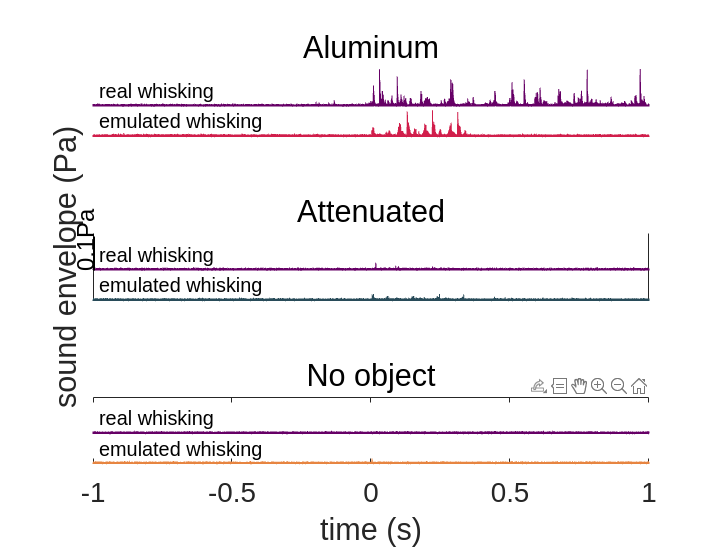

h = figure;
subplot(3,1,1)
plot(xTime,envelope(alumMouse(timeAlumMouse)),"Color",colorBen.purple)  
hold on
plot(xTime,envelope(aluminum(timeAlum))-0.09,"Color",colorBen.aluminum)
title('Aluminum','FontSize',12,'FontWeight','normal')
ylim([-0.089 0.11])
text(-0.98,0.05,'real whisking')
text(-0.98,-0.04,'emulated whisking')
set(gca,'FontSize',14)
set(gca,'FontName','SansSerif')
set(gca, 'xtick', [], 'ytick', []);
set(gca, 'XColor', 'none','YColor','none');


subplot(3,1,2)
plot(xTime,envelope(attMouse(timeAttMouse)),"Color",colorBen.purple)  
hold on
plot(xTime,envelope(attenuated(timeAtt))-0.09,"Color",colorBen.muted)
plot([-1 -1],[0.0 0.1],'k','LineWidth',2)
title('Attenuated','FontSize',12,'FontWeight','normal')
ylim([-0.089 0.11])
ylabel('sound envelope (Pa)')
text(-0.98,0.05,'real whisking')
text(-0.98,-0.04,'emulated whisking')
set(gca,'FontSize',14)
set(gca,'FontName','SansSerif')
set(gca, 'xtick', [],'ytick',[]);
set(gca, 'XColor', 'none');
text(-1.03,0,"0.1Pa",'FontSize',12,'FontWeight','normal','FontName','SansSerif','Rotation',90)

subplot(3,1,3)
plot(xTime,envelope(noMouse(timeNoMouse)),"Color",colorBen.purple)  
hold on
plot(xTime,envelope(noObject(timeNo))-0.09,"Color",colorBen.non)
title('No object','FontSize',12,'FontWeight','normal')
ylim([-0.089 0.11])
text(-0.98,0.05,'real whisking')
text(-0.98,-0.04,'emulated whisking')
xlabel('time (s)')
set(gca,'FontSize',14)
set(gca,'FontName','SansSerif')
set(gca, 'YColor','none');
set(gca,'ytick', []);
set(gcf,'Position',[2267,71,1058,807]);

AlumMouse = alumMouse(timeAlumMouse)

AlumMouse =     0.0006   -0.0010    0.0005   -0.0040    0.0011   -0.0011   -0.0035    0.0029    0.0003    0.0005   -0.0016    0.0001    0.0023    0.0032    0.0004    0.0001   -0.0034   -0.0018    0.0002   -0.0011   -0.0011    0.0011   -0.0011    0.0033    0.0009    0.0007   -0.0015   -0.0010   -0.0013    0.0005    0.0003    0.0028    0.0009   -0.0037    0.0010   -0.0020    0.0011    0.0031   -0.0014   -0.0017    0.0011   -0.0020    0.0055    0.0007   -0.0060    0.0003    0.0024    0.0030    0.0029   -0.0017


Alum = aluminum(timeAlum)

Alum =    -0.0010
    0.0009
    0.0002
    0.0005
    0.0026
    0.0006
    0.0003
    0.0011
    0.0029
    0.0005


AttMouse = attMouse(timeAttMouse)

AttMouse =     0.0005   -0.0012    0.0006    0.0008   -0.0016   -0.0015   -0.0017    0.0010    0.0002   -0.0033   -0.0018    0.0007   -0.0012   -0.0015    0.0006    0.0004    0.0010   -0.0019    0.0024    0.0008    0.0006   -0.0010    0.0026    0.0025   -0.0035    0.0002   -0.0036    0.0002    0.0002   -0.0015    0.0007   -0.0019    0.0007    0.0028   -0.0012    0.0008   -0.0016   -0.0015    0.0010    0.0006   -0.0016   -0.0017    0.0004    0.0008   -0.0014    0.0004    0.0010   -0.0017    0.0012    0.0008


Att = attenuated(timeAtt)

Att =     0.0025
    0.0003
   -0.0036
    0.0008
   -0.0019
    0.0005
   -0.0013
    0.0008
    0.0031
   -0.0018



meanAlM = mean(envelope(AlumMouse(250000:325000)))

meanAlM = 0.0063

meanAl = mean(envelope(Alum(250000:325000)))

meanAl = 0.0058

stdAlM = std(envelope(AlumMouse(250000:325000)))

stdAlM = 0.0074

stdAl = std(envelope(Alum(250000:325000)))

stdAl = 0.0050


meanAtM = mean(envelope(AttMouse(250000:325000)))

meanAtM = 0.0028

meanAt = mean(envelope(Att(250000:325000)))

meanAt = 0.0032

stdAtM = std(envelope(AttMouse(250000:325000)))

stdAtM = 0.0015

stdAt = std(envelope(Att(250000:325000)))

stdAt = 0.0018


maxAlM = max(envelope(AlumMouse(250000:325000)))

maxAlM = 0.1093

maxAl = max(envelope(Alum(250000:325000)))

maxAl = 0.0798


maxAtM = max(envelope(AttMouse(250000:325000)))

maxAtM = 0.0229

maxAt = max(envelope(Att(250000:325000)))

maxAt = 0.0215

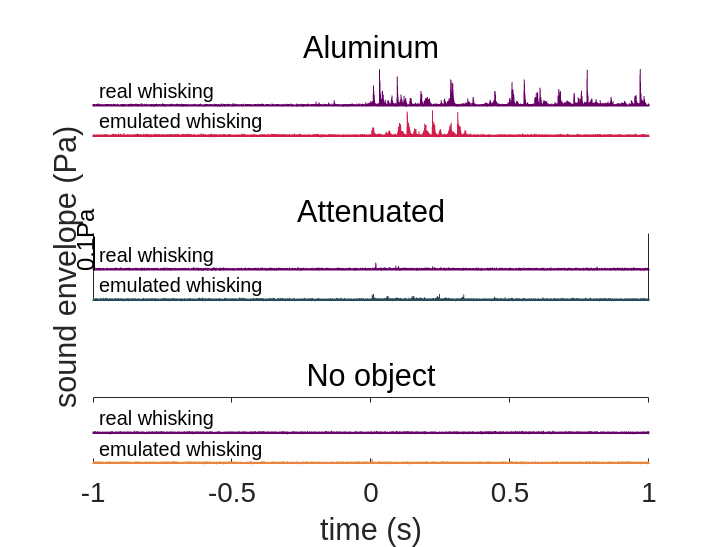

cd /media/ben/'Extreme SSD'/Thesis/figures/Fig2_IC_galvo/
saveas(h,'IC_sound.svg','svg')